addpath 'E:\MATLAB'
addpath 'E:\MATLAB'\'IMAGE SETS'\

ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'airplane.png';'arctichare.png';'girl.png';'lena.png';'monarch.png';'peppers1.tiff';'peppers2.png';'tulips.png'};
PSNR=zeros(size(ImageNames,1),1);
SSIM=zeros(size(ImageNames,1),1);
Entroppy=zeros(size(ImageNames,1),1);
Entropppy=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=imread(string);
    B=double(A(:,:,3));
%     B=double(rgb2gray(A));
    B1=bmn_decimation(B);
    SR=bmn_wavelet_SR_LoG1_51(B1);
    PSNR(i)=psnr(uint8(SR),uint8(B));
    SSIM(i)=ssim(uint8(SR),uint8(B));
    Entroppy(i)=entropy(uint8(SR));
    Entropppy(i)=entropy(uint8(uint8(B)));
end
toc

Elapsed time is 8.534762 seconds.


T=table(ImageNames,PSNR,SSIM,Entroppy,Entropppy)

T = 16×5 table
        ImageNames         PSNR      SSIM      Entroppy    Entropppy
    __________________    ______    _______    ________    _________

    {'aerial1.tiff'  }    38.938    0.90736     4.4897      4.6078  
    {'aerial2.tiff'  }    38.845    0.90389     4.6071      4.7036  
    {'aerial3.tiff'  }    35.451    0.85629     5.0474      5.1649  
    {'aerial4.tiff'  }     30.72    0.76828     6.5542      6.5896  
    {'aerial5.tiff'  }    34.208    0.76437     4.4514      4.6944  
    {'aerial6.tiff'  }    35.864     0.8292     4.8315      4.9461  
    {'aerial7.tiff'  }    39.208    0.92623     4.4224      4.5139  
    {'aerial8.tiff'  }    40.246    0.93665     4.2518      4.3366  
    {'airplane.png'  }    32.213    0.91542     6.2507      6.2138  
    {'arctichare.png'}    43.109    0.98254     5.7709 

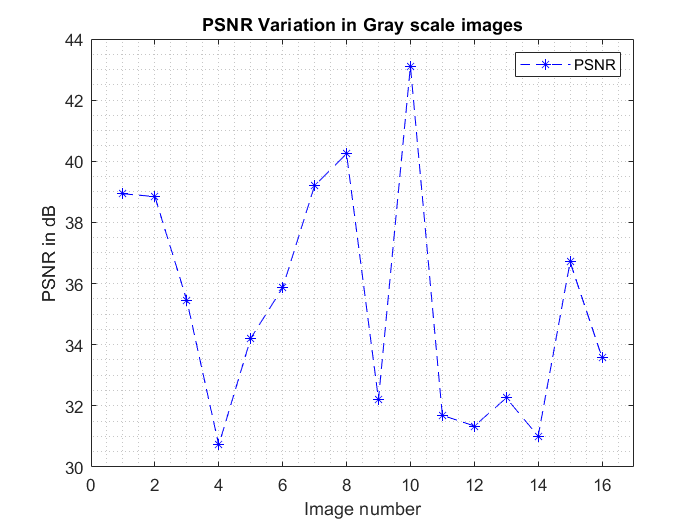

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\NGOCHOblue.xlsx'];
writetable(T,path_format)
n=1:size(ImageNames,1);
N=size(ImageNames,1);
figure;
plot(n,PSNR,'--b*')
xlim([0 N+1]);
grid minor
ylabel 'PSNR in dB'
xlabel 'Image number'
title ('PSNR Variation in Gray scale images','FontWeight','bold');
legend('PSNR')

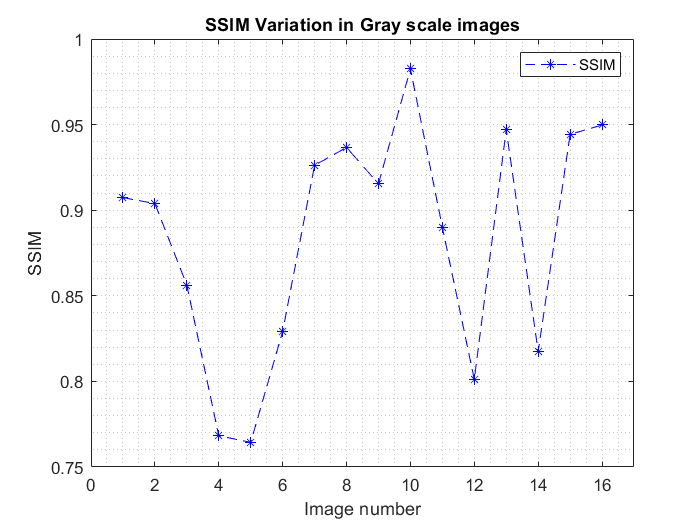

figure;
plot(n,SSIM,'--b*')
xlim([0 N+1]);
grid minor
ylabel 'SSIM'
xlabel 'Image number'
title ('SSIM Variation in Gray scale images','FontWeight','bold');
legend('SSIM')

function [SR]=bmn_wavelet_SR_LoG1_51(LR)
%This function carries out single image super-resolution. The input low
%resolution image is used as the low frequency approximation image. High
%frequency detail sub-bands are estimated by wavelet decomposition of a
%bicubic expansion of the inpout LR image. The initial super resolution
%image is further improved by back-projection using 5 x 5 LoG filter
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %
% Author: Boniface M. Ngocho %
% School of Engineering %
% University of Nairobi %
% 12th November 2015 %
% e-mail:bmnngocho@yahoo.co.uk %
% %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
GT2=bmn_bicubic(LR,2); % Enlarge LR image using bicubic interpolation
[A,H,V,D]=dwt2(GT2,'haar'); % DWT multiresolution
LR0=2.*double(LR); % Scale LR pixels
SR0=(idwt2(LR0,H,V,D,'haar')); %IDWT reconstruction
% Define back-projection filter
k=0.11;
b=-0.25; c=-2; d=-0.25;
a=1-(4*(b+c+d));
h1=[d 0 0 0 d;0 b c b 0;0 c a c 0;0 b c b 0;d 0 0 0 d];
h=k.*h1;
%Back Projection (3 steps)
[M,N]=size(LR);
Z=zeros(M,N);
SRin=SR0;
 for j=1:3
 LR1=bmn_decimation(SRin); %Calculate new LR image
 E1=LR-LR1; %Evaluate image error
 E11=imfilter(E1,h);
 E11=(double(E11)).*2;
 BP1=idwt2(E11,Z,Z,Z,'haar'); %Error Super Resolution
 SR1=SRin+BP1;
 SRin=SR1;
 end
SR=uint8(SRin);
end